# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SR2.mat'
sr = sr2;

sr.homeConfig();
q_0 = sr.q;
q_dot_0 = sr.q_dot;

Parameters

fileName = '';          % Where to save animation, Do not save if left as ''
animationTEnd = 10;     % When to stop animation time

simTime = '10.0';       % Simulation end time

% Forces
fx = 0;
fy = 0;
fz = 0;

nx = 0;
ny = 0;
nz = 0;

tau1 = 0;
tau2 = 0;
tau = [tau1; tau2];

f = 0.5;
dt = 1

dt = 1

### Launch Simulation

% profile on
tic
set_param('open_loop_dyn', 'StopTime', simTime)
simRes = sim('open_loop_dyn');
toc

Elapsed time is 3.390575 seconds.


% profile viewer
% profile off

### Animate Results

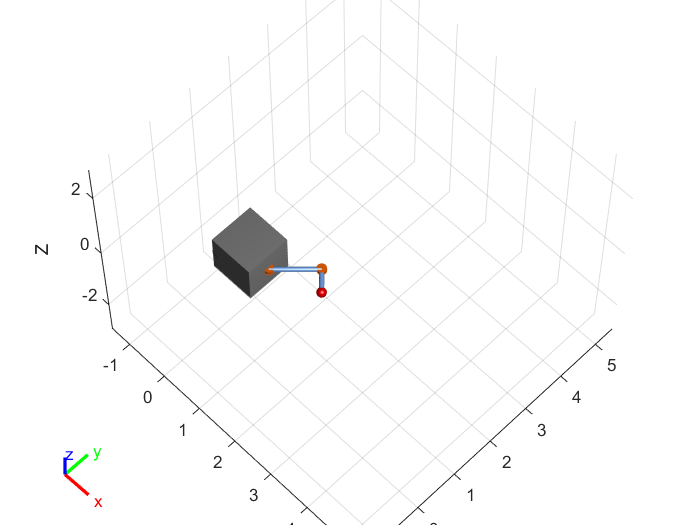

Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in SpaceRobot/animate (line 99)
        h_annot.set('String',str); 

clc
close all
folder = 'Project/Videos/';

data = simRes.q.getsampleusingtime(0, animationTEnd);

if ~strcmp(fileName, '')
    savePath = strcat(folder, fileName);
else
    savePath = '';
end

tic
sr.animate(data, 'fps', 17, 'rate', 1, 'fileName', savePath); 

toc